# **Lab 1**

*Joel Sundin, Pablo Gonzalez Baron*

- Histogram Equalization

We start by creating a histogram of the given image. We then calculate the cumulative sum of the histogram and normalizes this array so that it ranges from 0 to 1. Each pixel value and its corresponding equalized value is then mapped and the output is converted back to uint8.

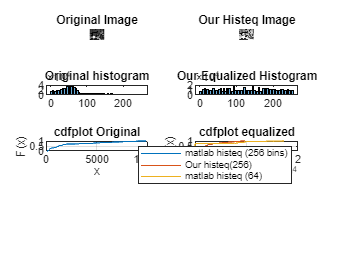

I = imread("images\greytoys.png");
my_histeq = myhisteq(I);
matlab_histeq_256_bins = histeq(I, 256);
matlab_histeq_64_bins = histeq(I);

figure
subplot(4, 2, 1)
imshow(I)
title('Original Image')

subplot(4, 2, 2)
imshow(my_histeq)
title('Our Histeq Image')

subplot(4, 2, 3)
histogram(I, 64)
title('Original histogram')

subplot(4, 2, 4)
histogram(my_histeq, 64)
title('Our Equalized Histogram')

%Original cdfplot
subplot(4, 2, 5);
cdfplot(imhist(I))
title('cdfplot Original')

%Original cdfplot
subplot(4, 2, 6);
cdfplot(imhist(matlab_histeq_256_bins))
hold on 
cdfplot(imhist(my_histeq))
hold on
cdfplot(imhist(matlab_histeq_64_bins))
legend('matlab histeq (256 bins)', 'Our histeq(256)', 'matlab histeq (64)')
title('cdfplot equalized')


function histeq = myhisteq(image)
    histogram = myhist(image);
    sum = cumsum(histogram);
    cdf = sum / sum(end);
    levels = 255;

    mapping = round((levels) * cdf);
    out = mapping(double(image) + 1);
    histeq = uint8(out);
end

function histogram = myhist(image)
    [rows, cols] = size(image);
    histogram = zeros(1, 256); % [0, 255]

    for i=1:1:rows
        for j=1:1:cols
            pixel_intensity = image(i, j);
            histogram(pixel_intensity + 1) = histogram(pixel_intensity + 1) + 1;
        end
    end
end